%%% This script is used to read the binary file produced by the DCA1000
%%% and Mmwave Studio
%%% Command to run in Matlab GUI -
%readDCA1000('<ADC capture bin file>') function [retVal] = readDCA1000(fileName)
%% global variables
% change based on sensor config
numADCSamples = 256; % number of ADC samples per chirp
numADCBits = 16; % number of ADC bits per sample
numRX = 4; % number of receivers
numLanes = 2; % do not change. number of lanes is always 2
isReal = 0; % set to 1 if real only data, 0 if complex data0
fileName = 'adc_data.bin';
%% read file
% read .bin file
fid = fopen(fileName,'r');
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
fileSize = size(adcData, 1);
% real data reshape, filesize = numADCSamples*numChirps
if isReal
    numChirps = fileSize/numADCSamples/numRX;
    LVDS = zeros(1, fileSize);
    %create column for each chirp
    LVDS = reshape(adcData, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
   else
    % for complex data
    % filesize = 2 * numADCSamples*numChirps
    numChirps = fileSize/2/numADCSamples/numRX;
    LVDS = zeros(1, fileSize/2);
    %combine real and imaginary part into complex data
    %read in file: 2I is followed by 2Q
counter = 1;
for i=1:4:fileSize-1
    LVDS(1,counter) = adcData(i) + sqrt(-1)*adcData(i+2); LVDS(1,counter+1) = adcData(i+1)+sqrt(-1)*adcData(i+3); counter = counter + 2;
end
% create column for each chirp
LVDS = reshape(LVDS, numADCSamples*numRX, numChirps);
%each row is data from one chirp
LVDS = LVDS.';
end
%organize data per RX
adcData = zeros(numRX,numChirps*numADCSamples);
for row = 1:numRX
    for i = 1: numChirps

    adcData(row, (i-1)*numADCSamples+1:i*numADCSamples) = LVDS(i, (row-1)*numADCSamples+1:row*numADCSamples);

end
end
% return receiver data
retVal = adcData;

adcData

adcData = 1.0e+02 *

  -1.0900 - 1.0000i  -0.4600 - 1.8500i   1.2500 - 2.1600i   2.6700 - 0.5500i   2.2300 + 1.4400i   0.7100 + 2.5800i  -1.1300 + 2.7600i  -2.6000 + 1.7200i  -3.0200 + 0.1600i  -2.7100 - 1.3500i  -1.5700 - 2.1900i  -0.5000 - 2.4700i   0.8000 - 2.1100i   1.4300 - 1.2800i   1.2000 - 0.5800i   1.2400 - 0.5100i   1.6800 + 0.0500i   1.4700 + 1.1800i   0.5900 + 1.9000i  -0.2400 + 1.9800i  -1.4300 + 1.7000i  -2.1800 + 0.9500i  -2.5500 + 0.1700i  -2.3300 - 1.2000i  -1.1400 - 2.3200i  -0.0800 - 2.2600i   1.1100 - 2.0300i   1.7600 - 1.1100i   1.6900 - 0.0400i   1.6000 + 0.6900i   0.8200 + 1.4000i  -0.1400 + 1.2700i  -0.3600 + 0.6300i  -0.1200 + 0.6400i  -0.4100 + 1.2500i  -1.2700 + 1.2600i  -2.0200 + 0.4000i  -1.9100 - 0.4200i  -1.4000 - 1.5000i  -0.1200 - 1.7600i   0.2000 - 1.3200i   0.8800 - 1.3000i   1.6900 - 0.4300i   1.6200 + 0.9400i   0.1900 + 1.9400i  -1.4900 + 1.0800i  -1.0600 - 0.5100i   0.4400 - 0.5500i   1.2400 + 0.7200i   0.0700 + 1.8800i
   1.2700 - 0.8100i   1.3800

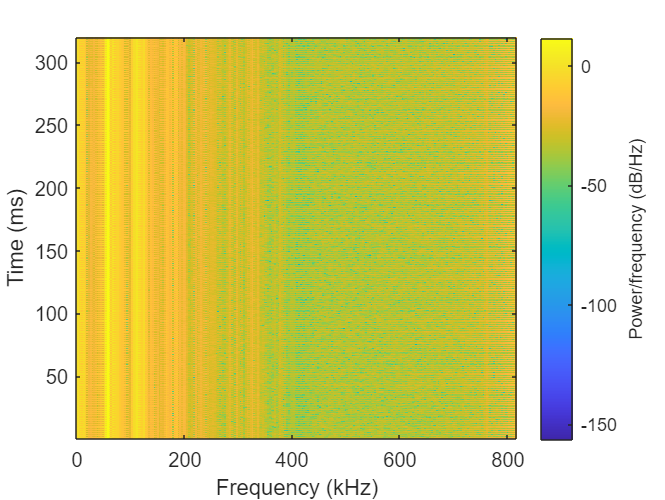




frame_time = .04;
n_frames = 8;
n_chirpspframe = 128;
n_adcsamples = 256;
x = adcData(1,1:end);

T = (frame_time/n_chirpspframe)/n_adcsamples;
fs = 1/T;

t = (0:(length(x)-1)*T);

Nfft = 2^nextpow2(length(x));
freqfft = (0:Nfft/2-1)*(fs/Nfft);
X = fft(x,Nfft);

Nspec = 256;
wspec = hamming(Nspec);
Noverlap = Nspec/2;

[SS,FF,TT] = spectrogram(x,wspec,Noverlap,Nspec,fs);


spectrogram(x,wspec,Noverlap,Nspec,fs)